load train.mat;
load test.mat;

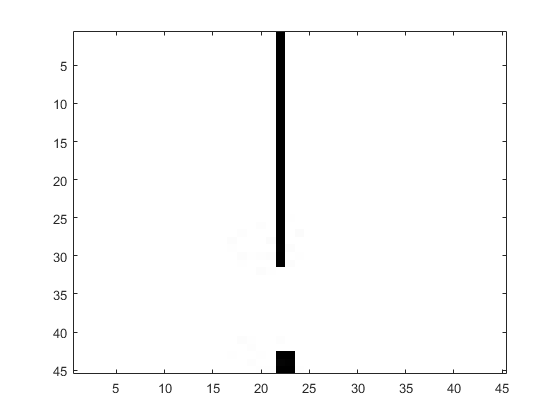

s = size(train_images{1});
for i=1:length(train_images)
    train_images{i} = reshape(train_images{i}, s(1)*s(2), []);
end
flat = double([train_images{:}]);
figure(); clf;
imagesc(reshape(flat(:, 1), 45, 45));
colormap gray;

imgs = flat - mean(mean(flat));

[V, D] = generate_eigenvectors(imgs', 128);

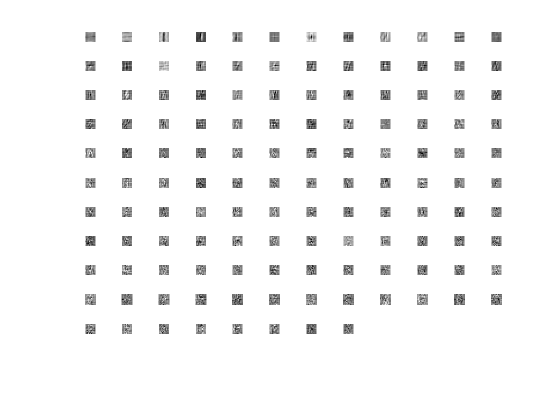

clf
subplot_size = ceil(sqrt(size(V, 2)));
for i = 1:size(V, 2)
    subplot(subplot_size, subplot_size, i);
    img_size = sqrt(size(V, 1));
    imagesc(reshape(V(:, i), [img_size img_size])); colormap('gray');
    axis equal;
    set(gca, 'visible', 'off');
end

save("eigenvectors.mat", "V", "D");

load eigenvectors.mat;

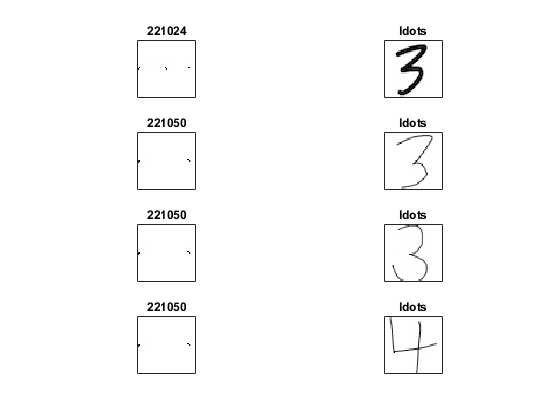

test_data = [img_load("test-data/3"); img_load("test-data/4");];
test_data = test_data - mean(mean(imgs));

train_data_projected = V'*imgs;
test_data_projected = V'*test_data';
rets = knnsearch(train_data_projected', test_data_projected');
figure(); clf;
for i=1:length(rets)
    img = imgs(:, rets(i));
    img_size = sqrt(length(img));
    img = reshape(img, [img_size img_size]);
    
    subplot(length(rets), 2, i * 2 - 1);
    imagesc(img); colormap('gray');
    axis equal; axis square;
    title(rets(i));
    set(gca,'xtick',[])
    set(gca,'ytick',[])
   
    subplot(length(rets), 2, i * 2);
    imagesc(reshape(test_data(i, :), img_size, img_size));
    axis equal; axis square;
    title(train_labels(rets(i)));
    set(gca,'xtick',[])
    set(gca,'ytick',[])
end